# Dummy maps for linear effects of stimlus intensity 

Model (6cond)

parameter:

- 6 Stimulus onset

- `    cue ``H``igh x stim ``H``igh (onset03_stim)`

- `    cue ``H``igh x stim ``M``ed`

- `    cue ``H``igh x stim ``L``ow`

- `    cue ``L``ow x stim ``H``igh`

- `    cue ``L``ow x stim ``M``ed`

- `    cue ``L``ow x stim ``L``ow`

- `C``ue: onset01_cue`

- `E``xpect rating: onset02_ratingexpect, pmod_expectRT`

- `O``utcome rating: onset04_ratingoutcome, pmod_outcomeRT`

- Motion covariate: 24DOF + CSF

- Spike, as many spikes detected by fmriprep (FD spike threshold 0.9)

# Pain only dummy maps 

# Linear effects of stimlus intensity (low < med < high)

#### Pain only :: load dataset

clear all;
close all;

contrast_of_interest = 'P_simple_stimlin_high_gt_low'

contrast_of_interest = 'P_simple_stimlin_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond/1stLevel';
contrast_name = {'P_VC_cue_high_gt_low', 'V_PC_cue_high_gt_low', 'C_PV_cue_high_gt_low', ...
'P_VC_stimlin_high_gt_low', 'V_PC_stimlin_high_gt_low', 'C_PV_stimlin_high_gt_low',...
'P_VC_stimquad_med_gt_other', 'V_PC_stimquad_med_gt_other', 'C_PV_stimquad_med_gt_other',...
'P_VC_cue_int_stimlin','V_PC_cue_int_stimlin', 'C_PV_cue_int_stimlin',...
'P_VC_cue_int_stimquad','V_PC_cue_int_stimquad','C_PV_cue_int_stimquad',...
'motor',...
'P_simple_cue_high_gt_low', 'V_simple_cue_high_gt_low', 'C_simple_cue_high_gt_low', ...
'P_simple_stimlin_high_gt_low', 'V_simple_stimlin_high_gt_low', 'C_simple_stimlin_high_gt_low',...
'P_simple_stimquad_med_gt_other', 'V_simple_stimquad_med_gt_other', 'C_simple_stimquad_med_gt_other',...
'P_simple_cue_int_stimlin', 'V_simple_cue_int_stimlin', 'C_simple_cue_int_stimlin',...
'P_simple_cue_int_stimquad','V_simple_cue_int_stimquad','C_simple_cue_int_stimquad'
};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 30749796 bytes
Loading image number:    77
Elapsed time is 3.530374 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7335020  Bit rate: 22.81 bits


#### Pain only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              19:34:32 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


#### Pain only :: Plot diagnostics, before l2norm

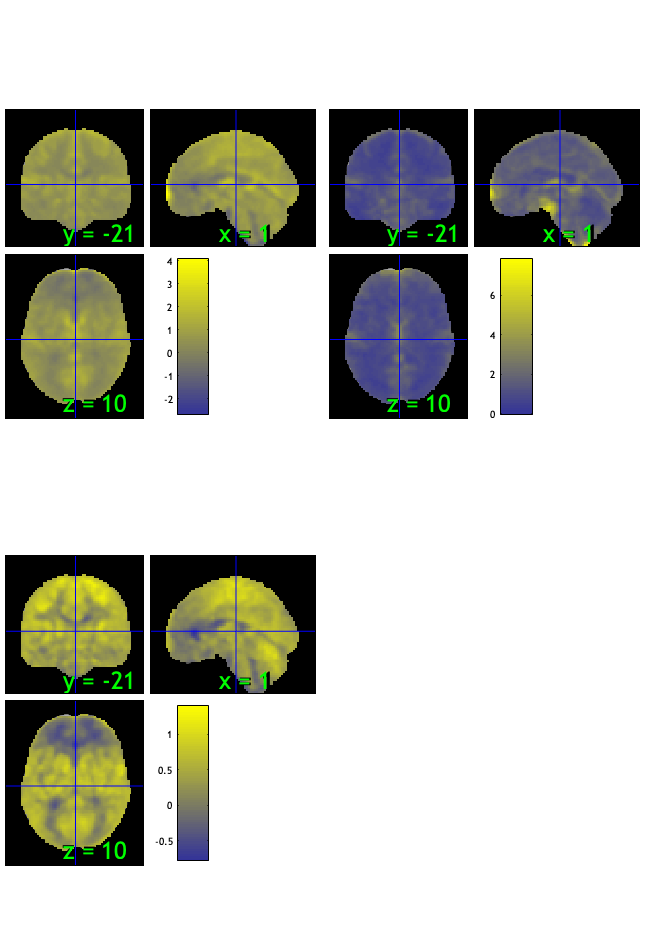

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 27.27%
Expected 3.85 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 48 58 
Uncorrected: 9 images		Cases 1 18 24 33 41 48 52 58 65 

Retained 12 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.65%
Expected 3.85 outside 95% ellipsoid, found   2

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 2 images		Cases 3 52 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                           

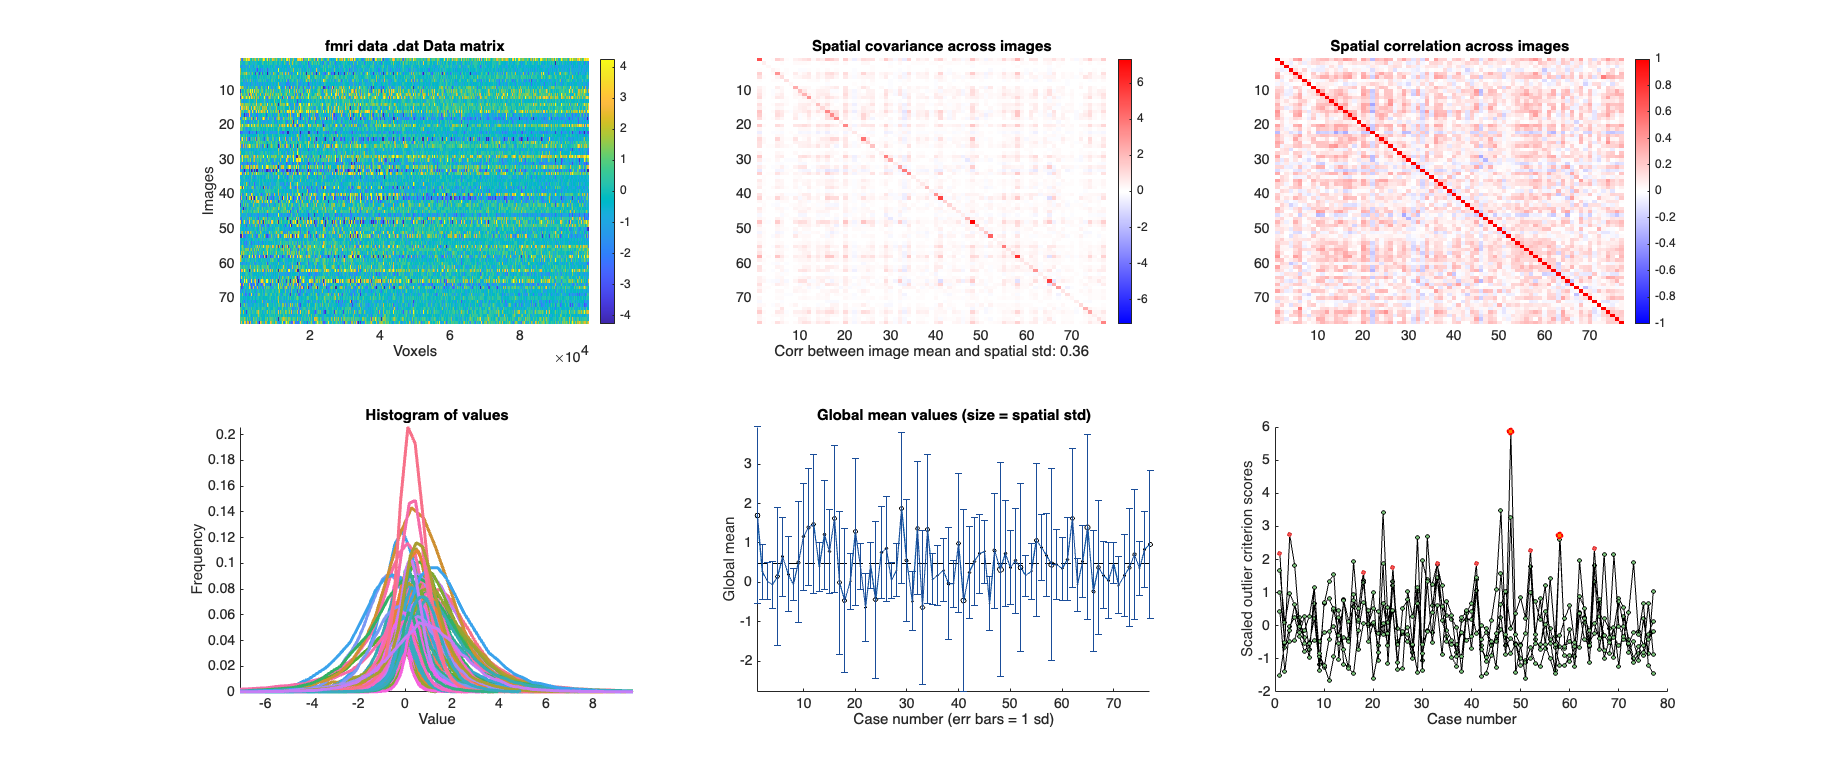

SPM12: spm_check_registration (v7759)              19:34:56 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Pain only :: run robfit

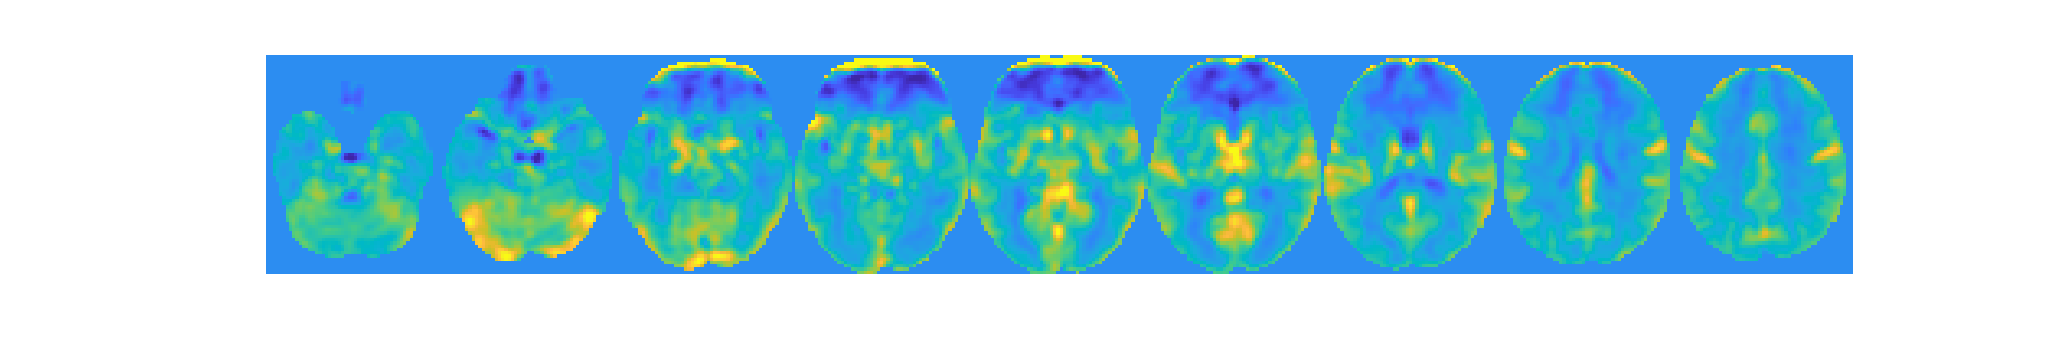

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### Pain only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 77


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 2 participants, size is now 75


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0093"    "participants that are outliers:... sub-0106"



disp(n);

    {'sub-0093'}    {'sub-0106'}



#### Pain only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


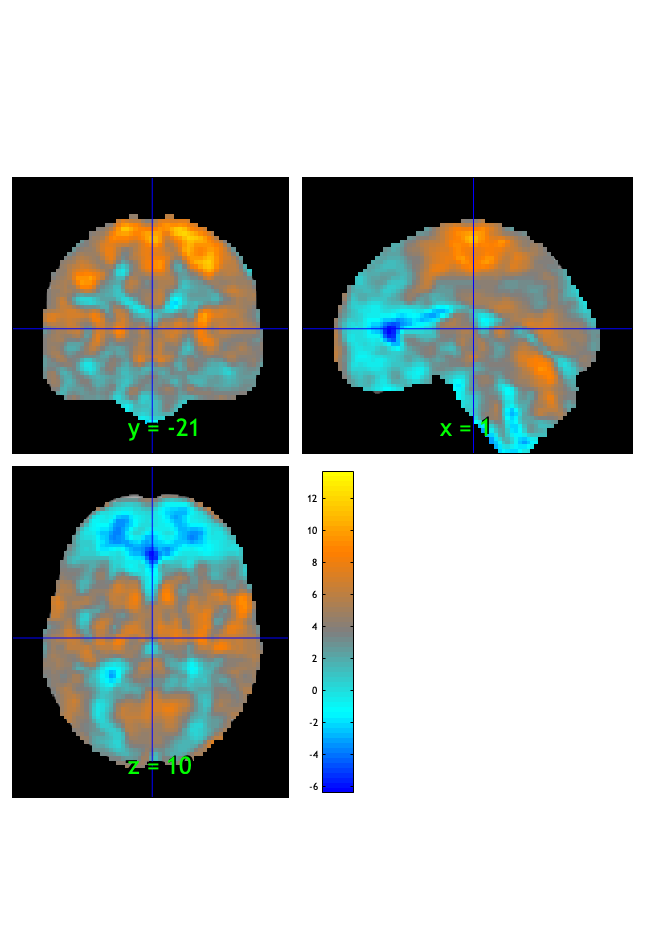

SPM12: spm_check_registration (v7759)              19:35:00 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.036206

Image   1
 21 contig. clusters, sizes   1 to 72088
Positive effect: 70296 voxels, min p-value: 0.00000000
Negative effect: 2006 voxels, min p-value: 0.00000000


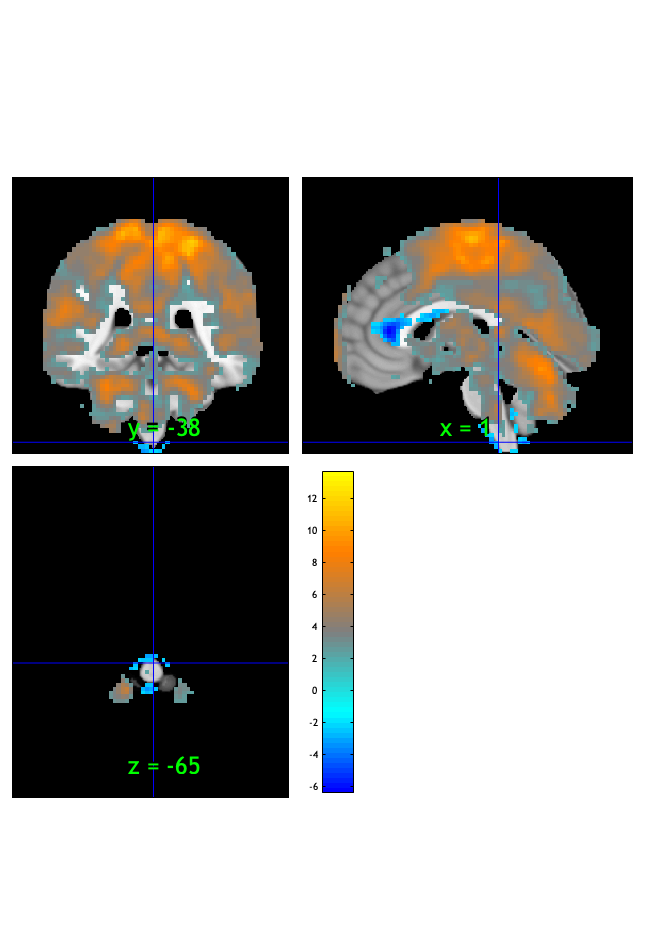

SPM12: spm_check_registration (v7759)              19:35:01 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t);

drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000434

Image   1
 51 contig. clusters, sizes   1 to 42177
Positive effect: 43103 voxels, min p-value: 0.00000000
Negative effect: 209 voxels, min p-value: 0.00000000


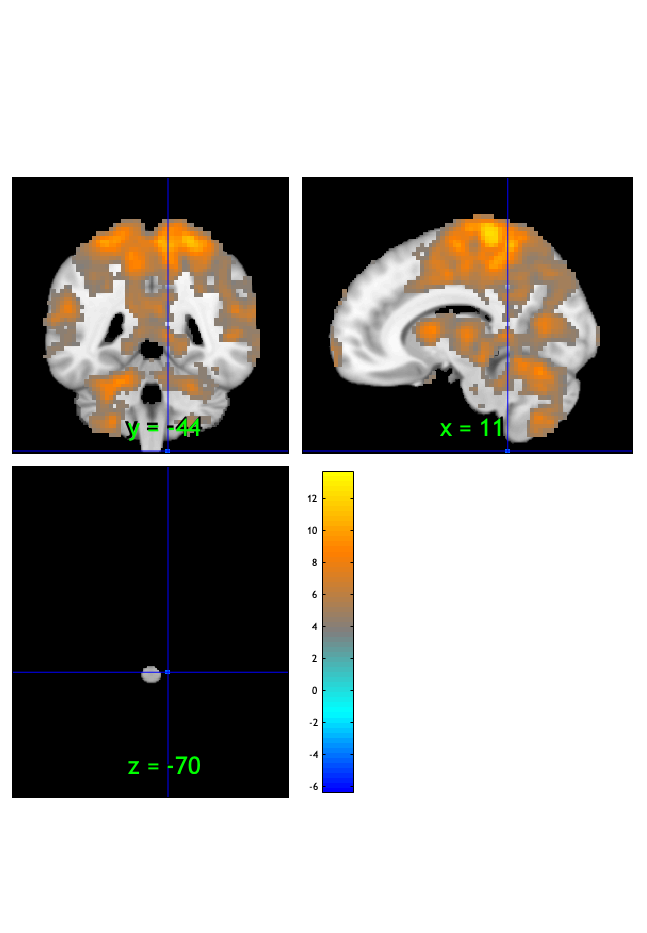

SPM12: spm_check_registration (v7759)              19:35:02 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


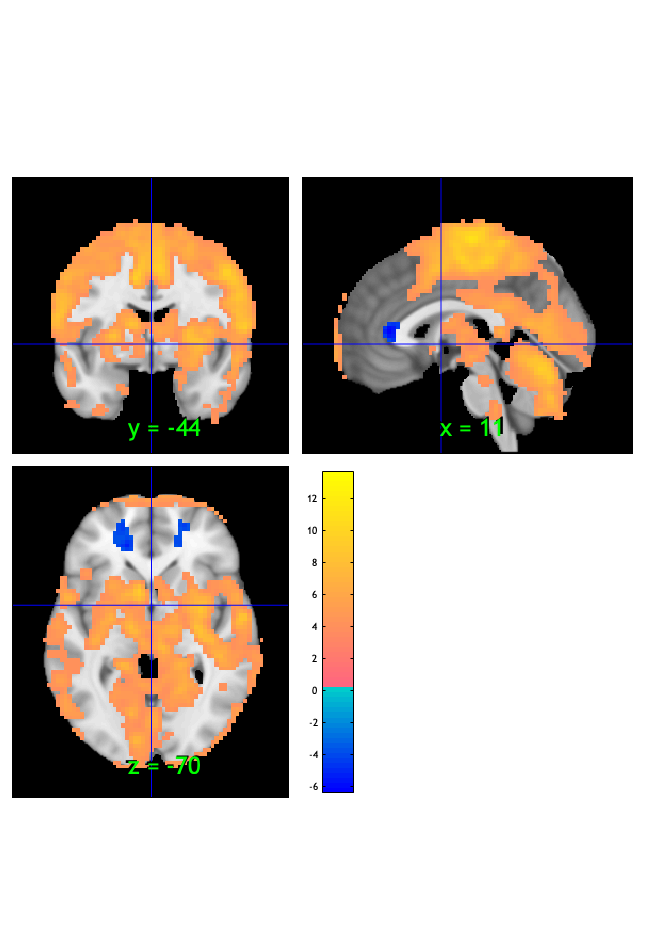

orthviews(fdr_t);

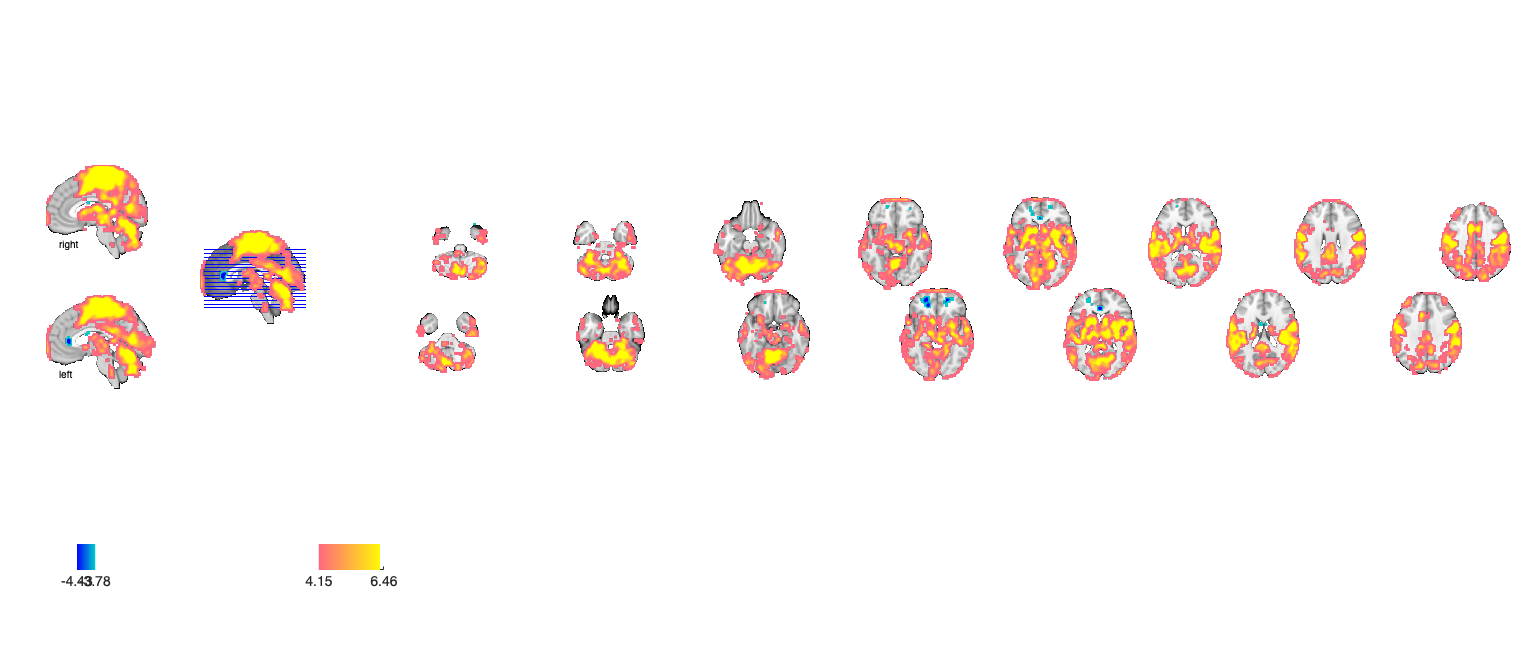

Setting up fmridisplay objects
sagittal montage: 1095 voxels displayed, 42217 not displayed on these slices
sagittal montage: 1180 voxels displayed, 42132 not displayed on these slices
sagittal montage: 998 voxels displayed, 42314 not displayed on these slices
axial montage: 7221 voxels displayed, 36091 not displayed on these slices
axial montage: 7774 voxels displayed, 35538 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;

#### Pain only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low       testr_high       words_high    
    _________    ______________    __________    _________________

    -0.16339     {'trait'     }     0.27892      {'motor'        }
    -0.15637     {'judgment'  }     0.27043      {'movements'    }
    -0.15263     {'depression'}     0.24352      {'sensorimotor' }
    -0.15093     {'disorder'  }     0.22677      {'finger'       }
      -0.149     {'affect'    }     0.22446      {'hand'         }
    -0.14678     {'social'    }     0.20478      {'somatosensory'}
    -0.13876     {'face'      }     0.20279      {'sensory'      }
     -0.1363     {'neutral'   }     0.20087      {'muscle'       }
    -0.13478     {'faces'     }     0.20078      {'execution'    }
    -0.13312     {'affe

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Pain only :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	0.0055	0.9045	0.3686	0.0000	
Cog Wholebrain	0.0112	2.8465	0.0057	1.0000	
Emo Wholebrain	-0.0152	-2.7633	0.0072	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d
    ___________________    __________    _________    _______    _________    ________

    {'Pain Wholebrain'}    0.0054686     0.0060853    0.89865      0.37168     0.10241
    {'Cog Wholebrain' }     0.011212     0.0039393     2.8462    0.0056846     0.32436
    {'Emo Wholebrain' }    -0.015218     0.0055087    -2.7625    0.0071902    -0.31482



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {77×3 cell}
        text_han: {77×3 cell}
       point_han: {77×3 cell}
    star_handles: [11.0016 12.0016 13.0016]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d
    ___________________    __________    _________    _______    _________    ________

    {'Pain Wholebrain'}    0.0086162     0.0059202     1.4554      0.14968     0.16586
    {'Cog Wholebrain' }     0.010483     0.0036567     2.8668    0.0053617     0.32671
    {'Emo Wholebrain' }    -0.017913     0.0053967    -3.3193    0.0013876    -0.37827



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {77×3 cell}
        text_han: {77×3 cell}
       point_han: {77×3 cell}
    star_handles: [14.0016 15.0016 16.0015]


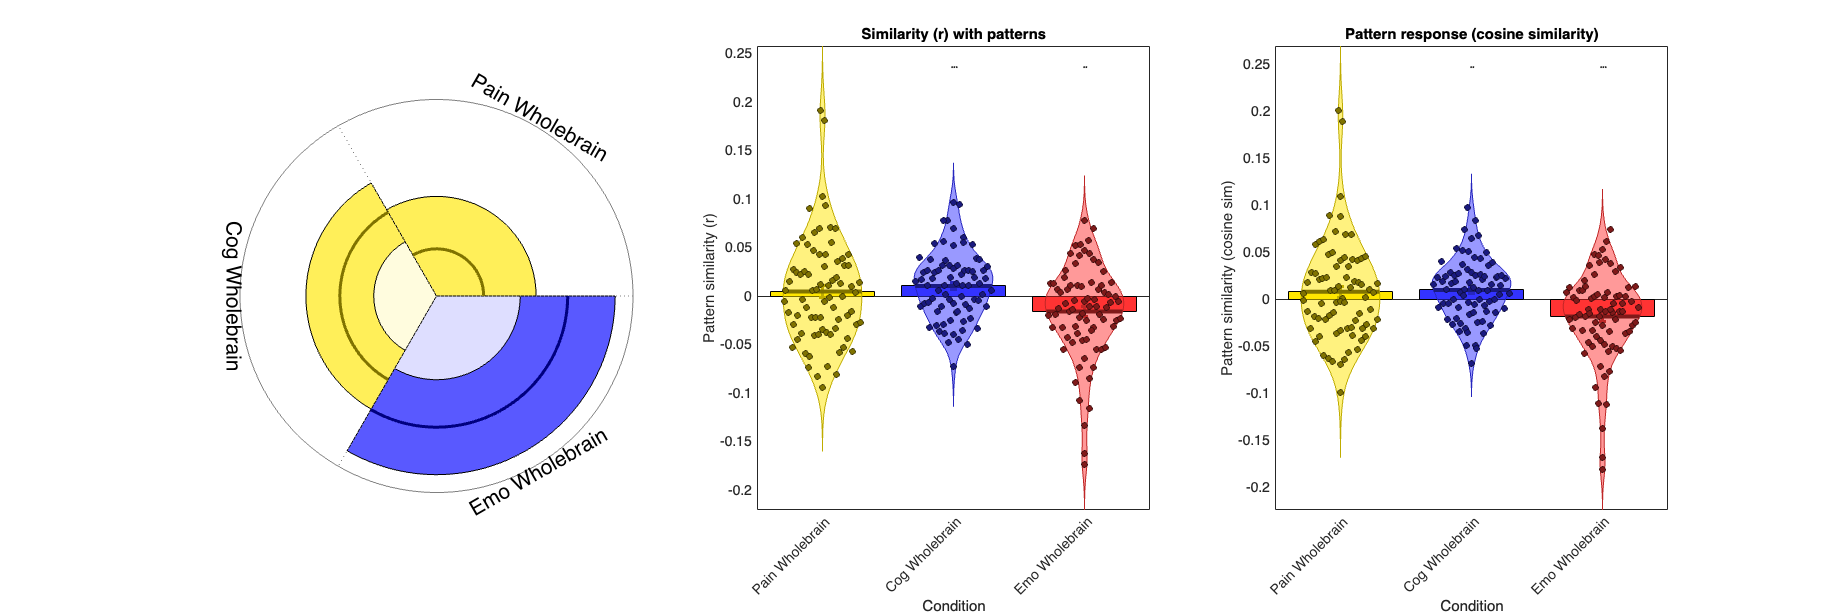

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Vicarious only dummy maps 

# Linear effects of stimlus intensity (low < med < high)

clear all;
close all;

#### Vicarious only :: load dataset

contrast_of_interest = 'V_simple_stimlin_high_gt_low'

contrast_of_interest = 'V_simple_stimlin_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond/1stLevel';
contrast_name = {'P_VC_cue_high_gt_low', 'V_PC_cue_high_gt_low', 'C_PV_cue_high_gt_low', ...
'P_VC_stimlin_high_gt_low', 'V_PC_stimlin_high_gt_low', 'C_PV_stimlin_high_gt_low',...
'P_VC_stimquad_med_gt_other', 'V_PC_stimquad_med_gt_other', 'C_PV_stimquad_med_gt_other',...
'P_VC_cue_int_stimlin','V_PC_cue_int_stimlin', 'C_PV_cue_int_stimlin',...
'P_VC_cue_int_stimquad','V_PC_cue_int_stimquad','C_PV_cue_int_stimquad',...
'motor',...
'P_simple_cue_high_gt_low', 'V_simple_cue_high_gt_low', 'C_simple_cue_high_gt_low', ...
'P_simple_stimlin_high_gt_low', 'V_simple_stimlin_high_gt_low', 'C_simple_stimlin_high_gt_low',...
'P_simple_stimquad_med_gt_other', 'V_simple_stimquad_med_gt_other', 'C_simple_stimquad_med_gt_other',...
'P_simple_cue_int_stimlin', 'V_simple_cue_int_stimlin', 'C_simple_cue_int_stimlin',...
'P_simple_cue_int_stimquad','V_simple_cue_int_stimquad','C_simple_cue_int_stimquad'
};
index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI'); 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';

con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 30749796 bytes
Loading image number:    77
Elapsed time is 3.396587 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7367459  Bit rate: 22.81 bits


#### Vicarious only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              19:02:25 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Vicarious only :: Plot diagnostics, before l2norm

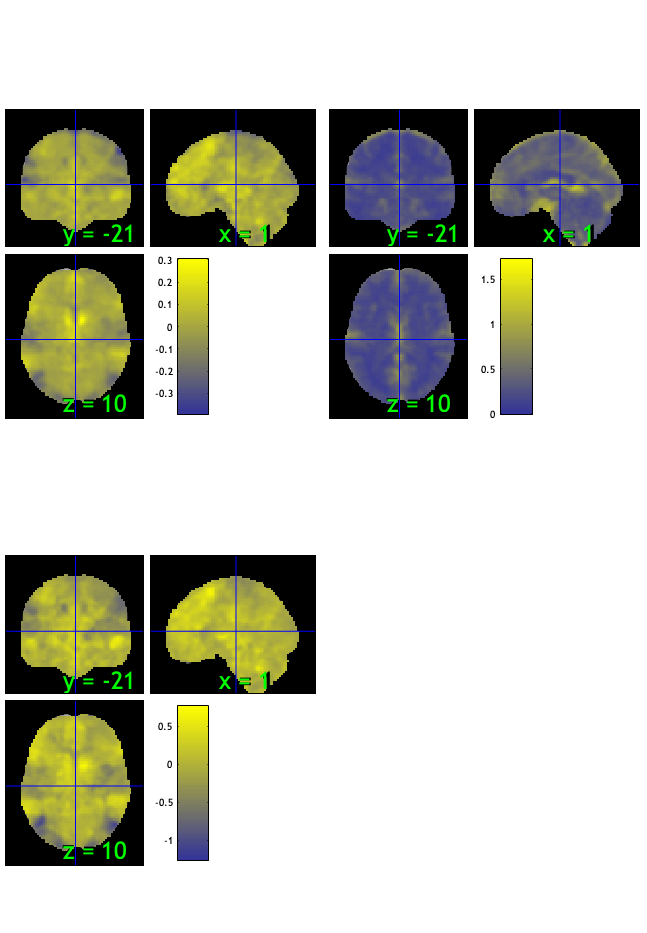

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 23.38%
Expected 3.85 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 4 images		Cases 42 52 62 69 
Uncorrected: 5 images		Cases 42 43 52 62 69 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 55.84%
Expected 3.85 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  4 images 
                               Outlier_count    Percentage
                               

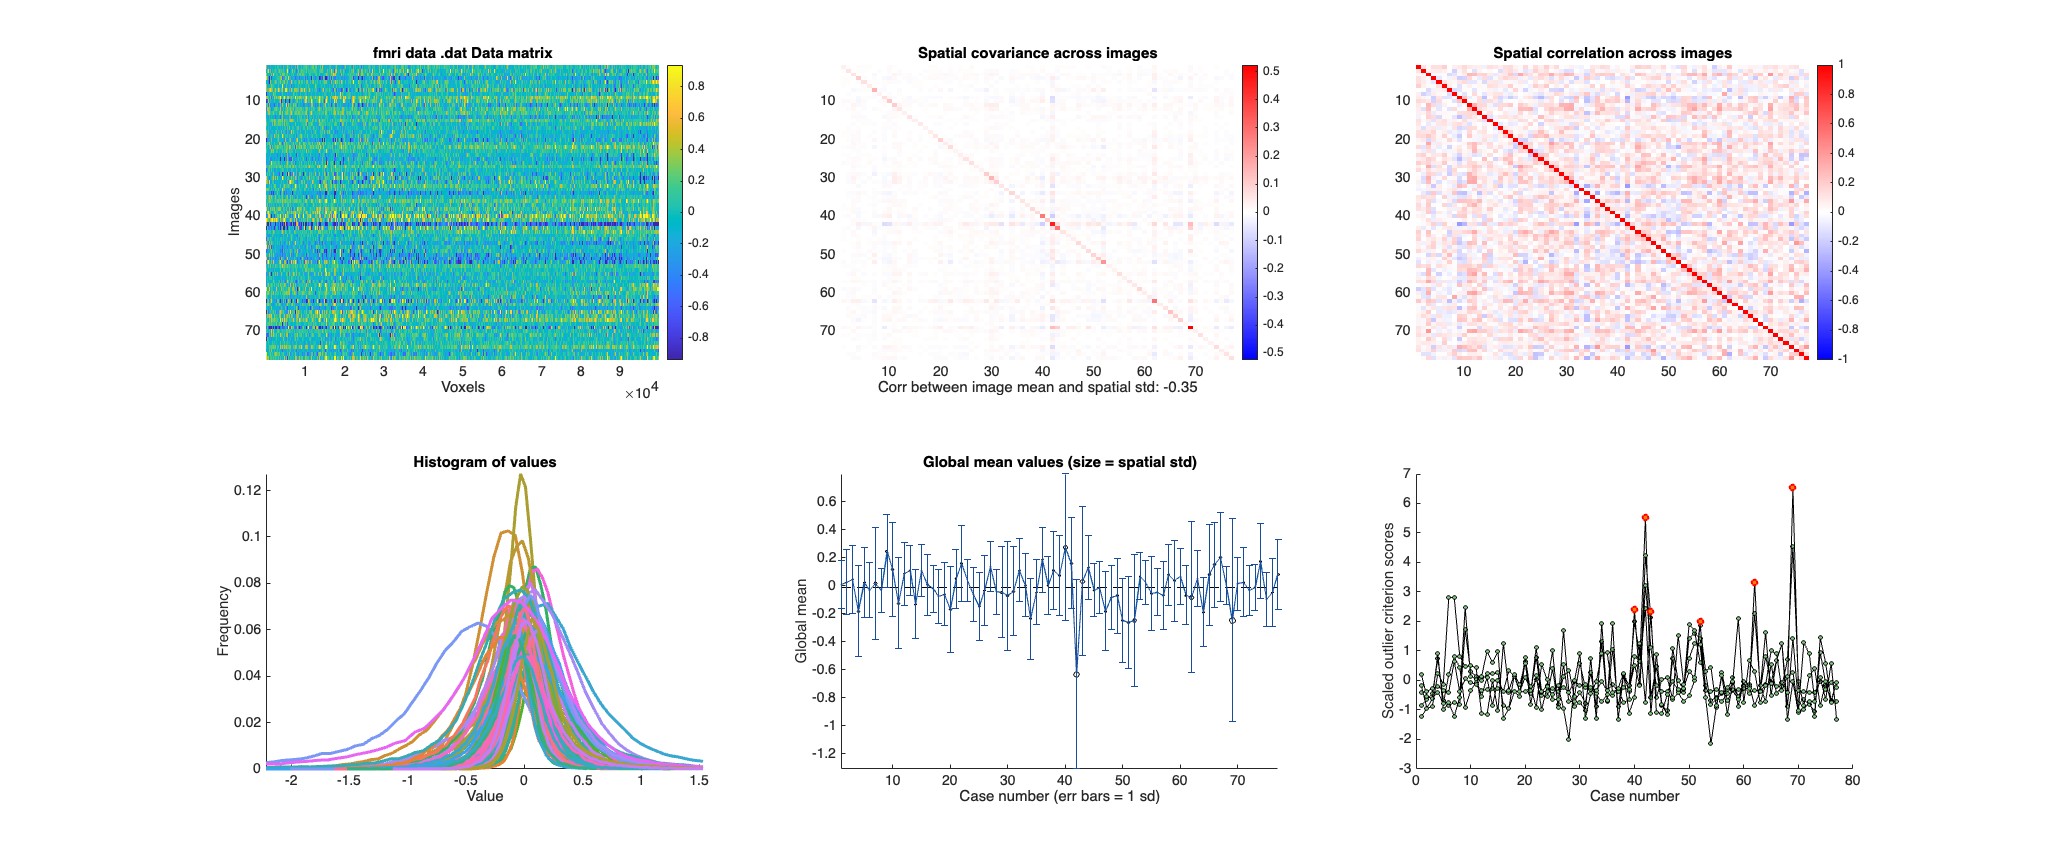

SPM12: spm_check_registration (v7759)              19:02:52 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Vicarious only :: run robfit

set(gcf,'Visible','on');
figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 77


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 6 participants, size is now 71


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are out…"    "participants that are out…"    "participants that are out…"    "participants that are out…"    "participants that are out…"    "participants that are out…"



disp(n);

    {'sub-0082'}    {'sub-0085'}    {'sub-0086'}    {'sub-0098'}    {'sub-0114'}    {'sub-0123'}



#### Vicarious only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


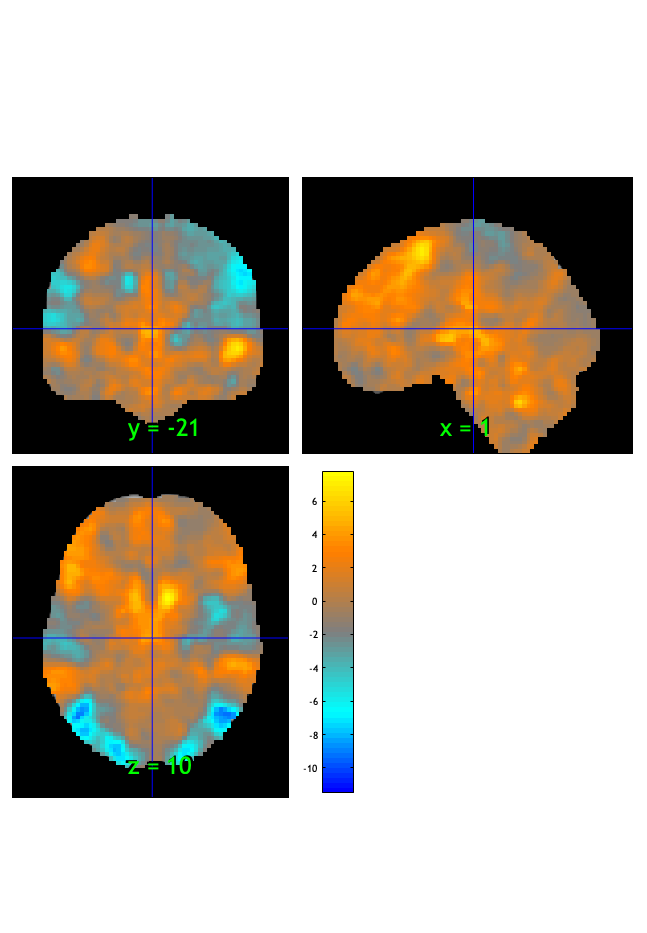

SPM12: spm_check_registration (v7759)              19:02:56 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.009568

Image   1
 85 contig. clusters, sizes   1 to 6415
Positive effect: 7835 voxels, min p-value: 0.00000000
Negative effect: 11271 voxels, min p-value: 0.00000000


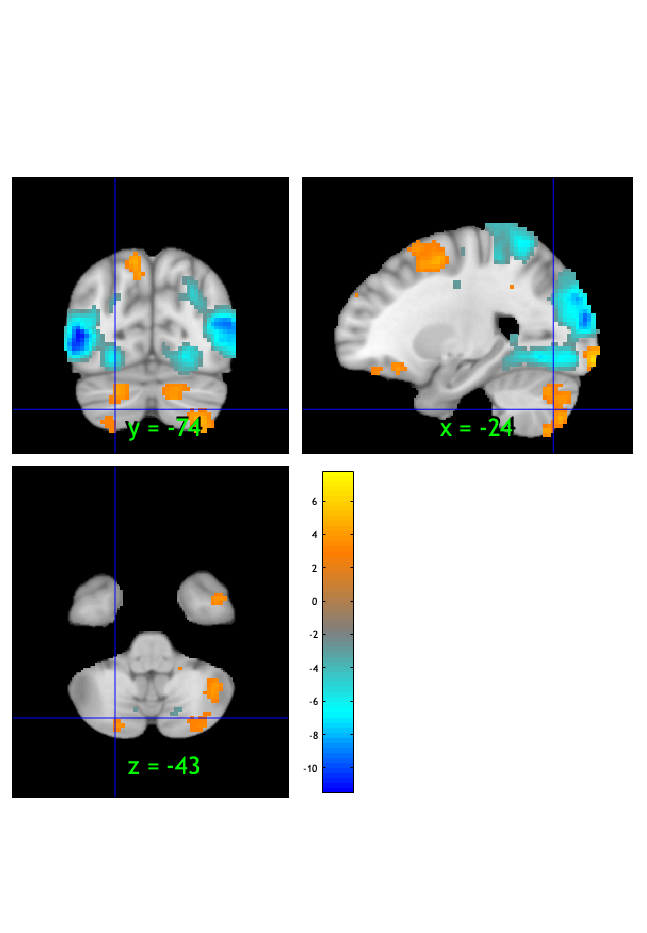

SPM12: spm_check_registration (v7759)              19:02:58 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t);

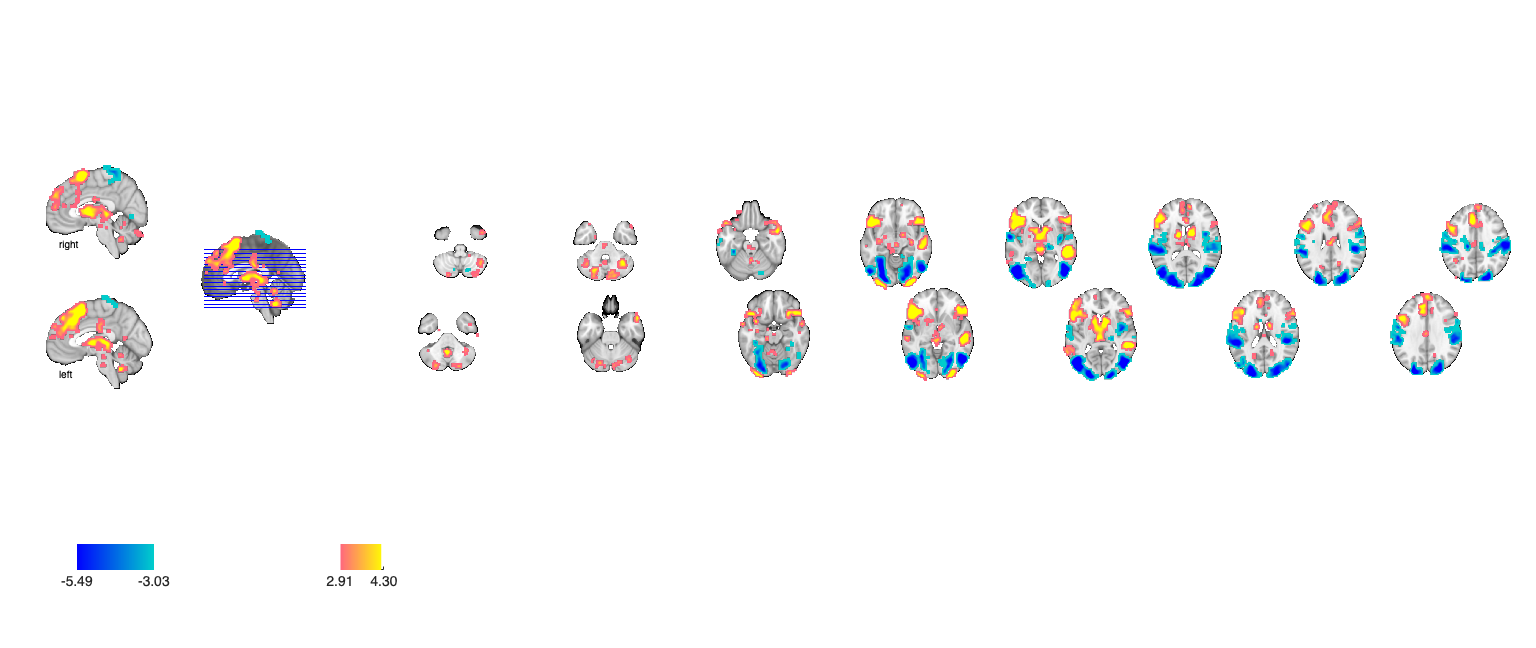

Setting up fmridisplay objects
sagittal montage: 374 voxels displayed, 18732 not displayed on these slices
sagittal montage: 339 voxels displayed, 18767 not displayed on these slices
sagittal montage: 363 voxels displayed, 18743 not displayed on these slices
axial montage: 3416 voxels displayed, 15690 not displayed on these slices
axial montage: 3683 voxels displayed, 15423 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;

#### Vicarious only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low      testr_high     words_high  
    _________    _____________    __________    _____________

    -0.36821     {'motion'   }     0.26434      {'verb'     }
    -0.34545     {'visual'   }     0.26178      {'verbal'   }
    -0.31976     {'spatial'  }     0.21597      {'word'     }
       -0.29     {'hand'     }     0.21441      {'retrieval'}
    -0.28921     {'tactile'  }     0.20998      {'reward'   }
    -0.28463     {'shape'    }      0.2049      {'memory'   }
    -0.27063     {'object'   }     0.19316      {'affect'   }
    -0.26561     {'objects'  }     0.19281      {'semantic' }
      -0.259     {'eye'      }     0.18938      {'sentences'}
    -0.25617     {'movements'}     0.18332      {'correct'  }



Vicarious only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0078	-1.2076	0.2309	0.0000	
Cog Wholebrain	-0.0007	-0.1879	0.8514	0.0000	
Emo Wholebrain	0.0080	1.1843	0.2400	0.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value     Std_Error       T           P       Cohens_d 
    ___________________    ___________    _________    ________    _______    _________

    {'Pain Wholebrain'}     -0.0077852    0.0064453     -1.2079    0.23084     -0.13765
    {'Cog Wholebrain' }    -0.00073442    0.0039122    -0.18773    0.85159    -0.021394
    {'Emo Wholebrain' }      0.0080263    0.0067727      1.1851    0.23968      0.13505



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {77×3 cell}
        text_han: {77×3 cell}
       point_han: {77×3 cell}
    star_handles: [11.0013 12.0013 13.0013]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value     Std_Error       T           P       Cohens_d 
    ___________________    ___________    _________    ________    _______    _________

    {'Pain Wholebrain'}     -0.0075599    0.0063081     -1.1984    0.23447     -0.13657
    {'Cog Wholebrain' }    -0.00087106    0.0036306    -0.23992    0.81104    -0.027342
    {'Emo Wholebrain' }      0.0080456    0.0066574      1.2085     0.2306      0.13772



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {77×3 cell}
        text_han: {77×3 cell}
       point_han: {77×3 cell}
    star_handles: [14.0013 15.0013 16.0012]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Cognitive only dummy maps 

# Linear effects of stimlus intensity (low < med < high)

#### Cognitive only :: load dataset

clear all; close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0022.nii'));
spm('Defaults','fMRI');
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 30749796 bytes
Loading image number:    77
Elapsed time is 3.255422 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7365728  Bit rate: 22.81 bits


contrast_name = {'P_VC_cue_high_gt_low', 'V_PC_cue_high_gt_low', 'C_PV_cue_high_gt_low', ...
'P_VC_stimlin_high_gt_low', 'V_PC_stimlin_high_gt_low', 'C_PV_stimlin_high_gt_low',...
'P_VC_stimquad_med_gt_other', 'V_PC_stimquad_med_gt_other', 'C_PV_stimquad_med_gt_other',...
'P_VC_cue_int_stimlin','V_PC_cue_int_stimlin', 'C_PV_cue_int_stimlin',...
'P_VC_cue_int_stimquad','V_PC_cue_int_stimquad','C_PV_cue_int_stimquad',...
'motor',...
'P_simple_cue_high_gt_low', 'V_simple_cue_high_gt_low', 'C_simple_cue_high_gt_low', ...
'P_simple_stimlin_high_gt_low', 'V_simple_stimlin_high_gt_low', 'C_simple_stimlin_high_gt_low',...
'P_simple_stimquad_med_gt_other', 'V_simple_stimquad_med_gt_other', 'C_simple_stimquad_med_gt_other',...
'P_simple_cue_int_stimlin', 'V_simple_cue_int_stimlin', 'C_simple_cue_int_stimlin',...
'P_simple_cue_int_stimquad','V_simple_cue_int_stimquad','C_simple_cue_int_stimquad'
};

#### Cognitive only :: `check data coverage`

m = mean(con_data_obj);
% m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              19:03:50 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


#### Cognitive only :: Plot diagnostics, before l2norm

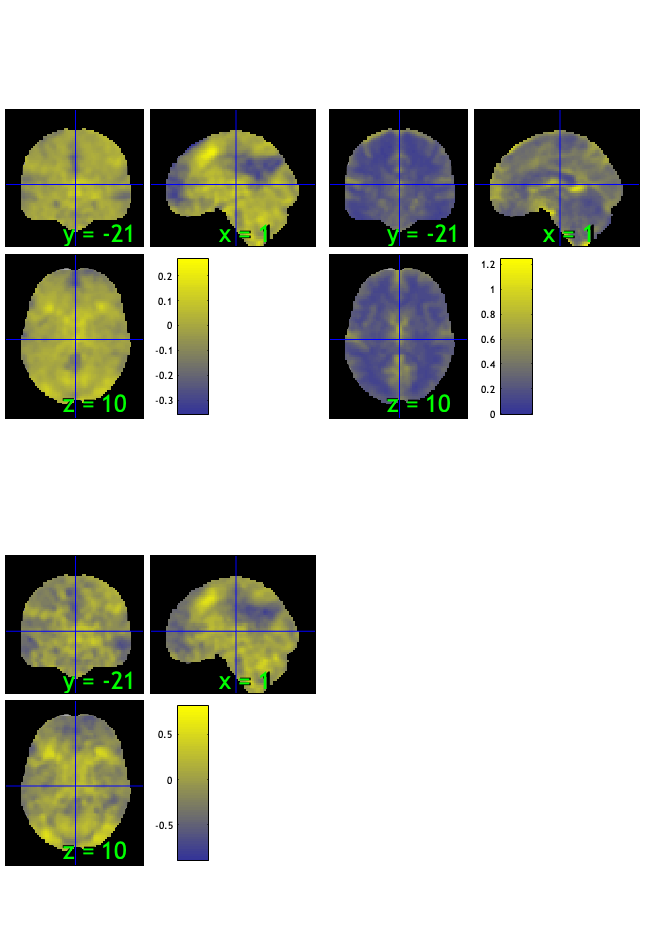

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 20.78%
Expected 3.85 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 40 67 69 
Uncorrected: 4 images		Cases 40 42 67 69 

Retained 13 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.65%
Expected 3.85 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 63 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                               _

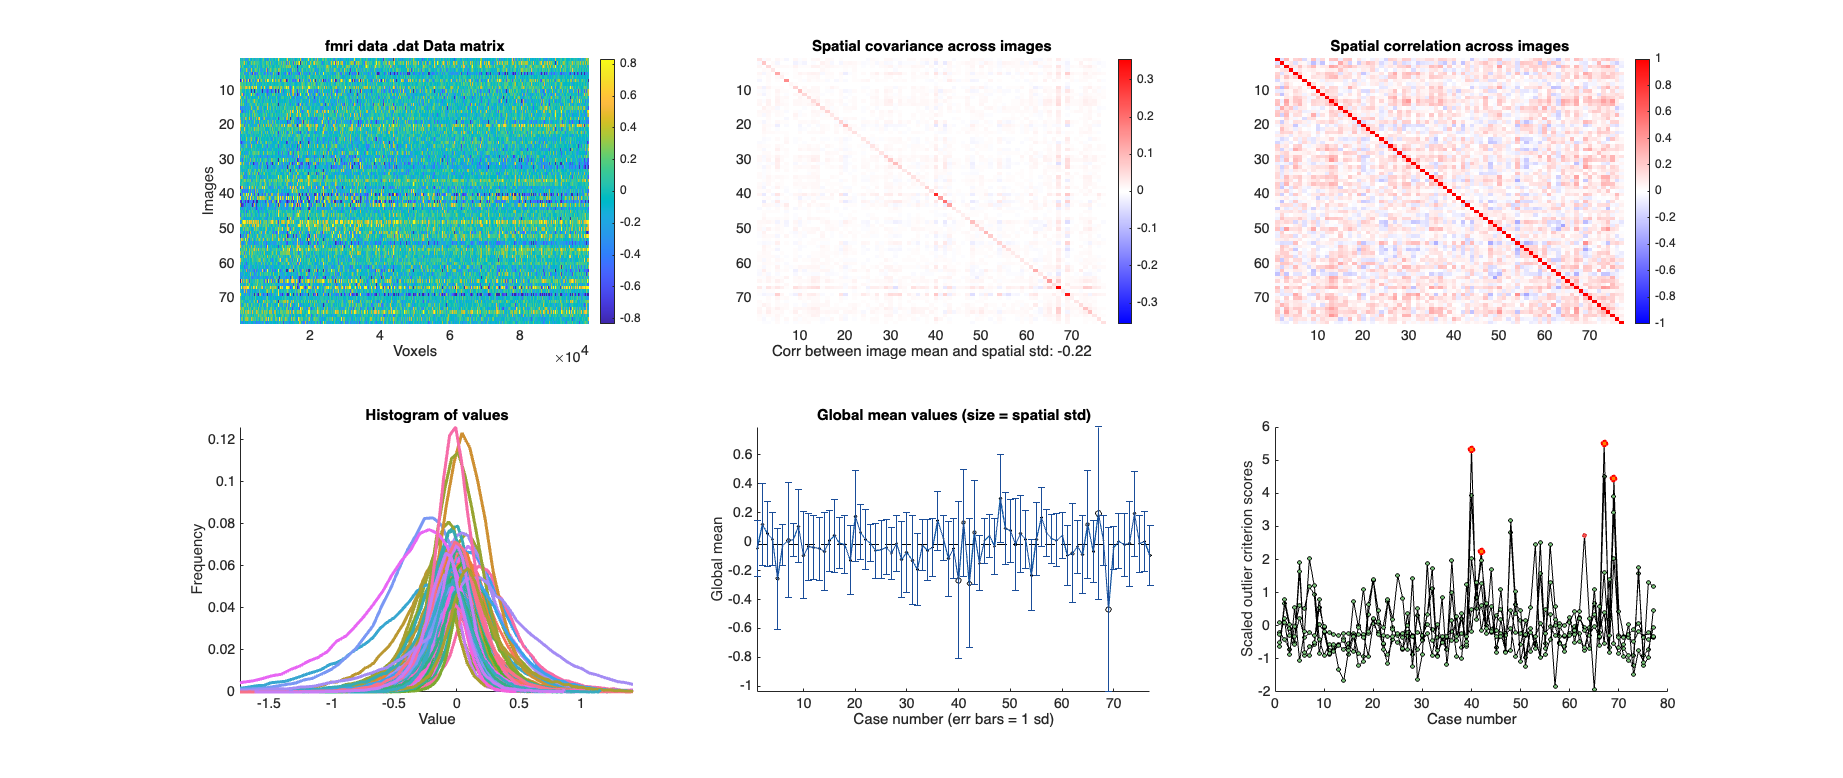

SPM12: spm_check_registration (v7759)              19:04:14 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Cognitive only :: run robfit

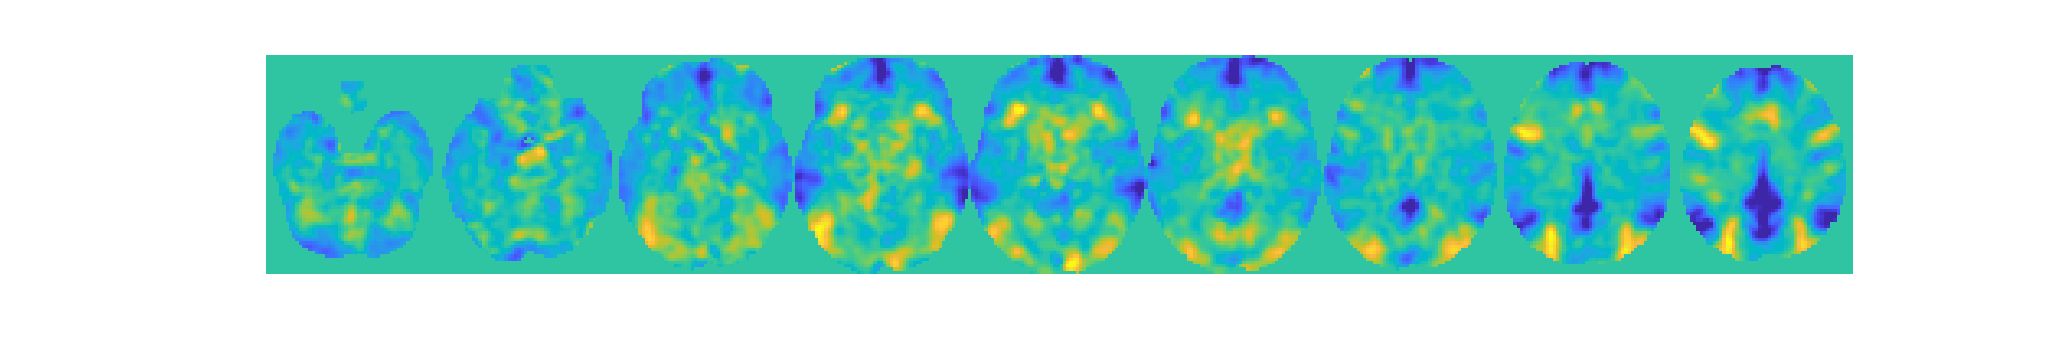

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 77


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 4 participants, size is now 73


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0082"    "participants that are outliers:... sub-0085"    "participants that are outliers:... sub-0120"    "participants that are outliers:... sub-0123"



disp(n);

    {'sub-0082'}    {'sub-0085'}    {'sub-0120'}    {'sub-0123'}



#### Cognitive only:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


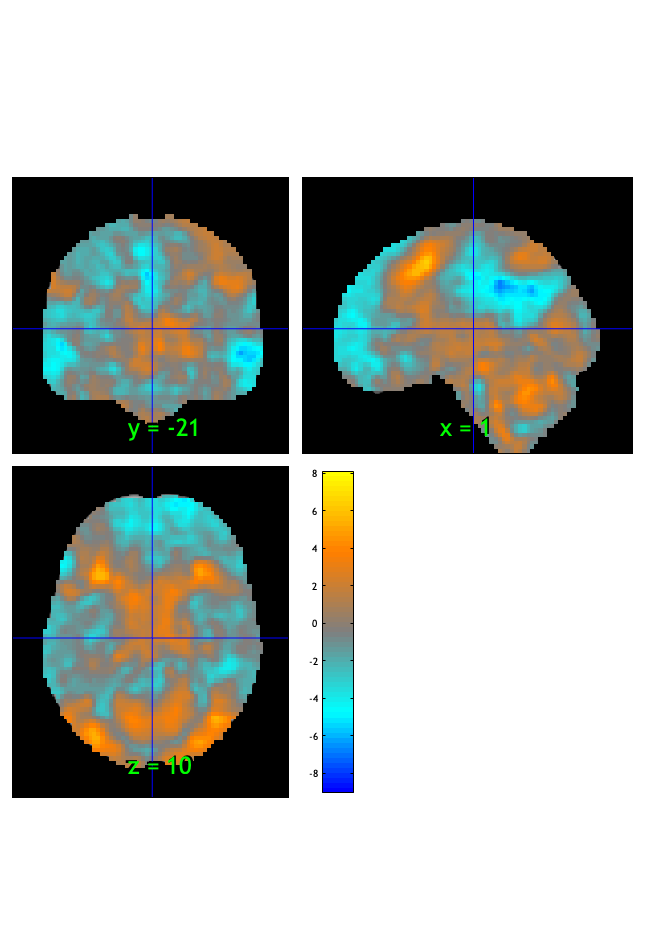

SPM12: spm_check_registration (v7759)              19:04:18 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.011560

Image   1
123 contig. clusters, sizes   1 to 6242
Positive effect: 9213 voxels, min p-value: 0.00000000
Negative effect: 13870 voxels, min p-value: 0.00000000


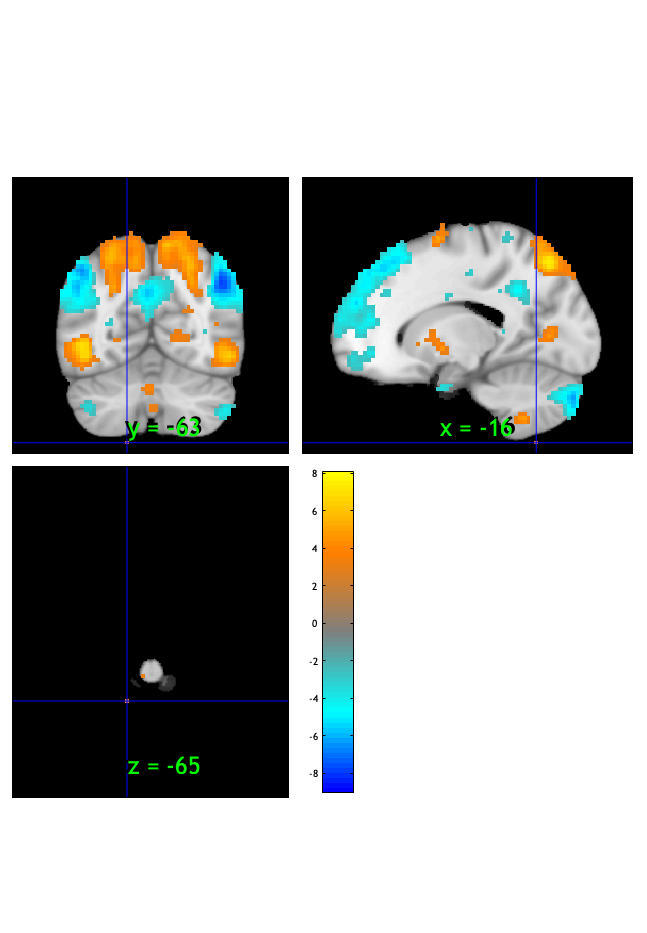

SPM12: spm_check_registration (v7759)              19:04:19 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


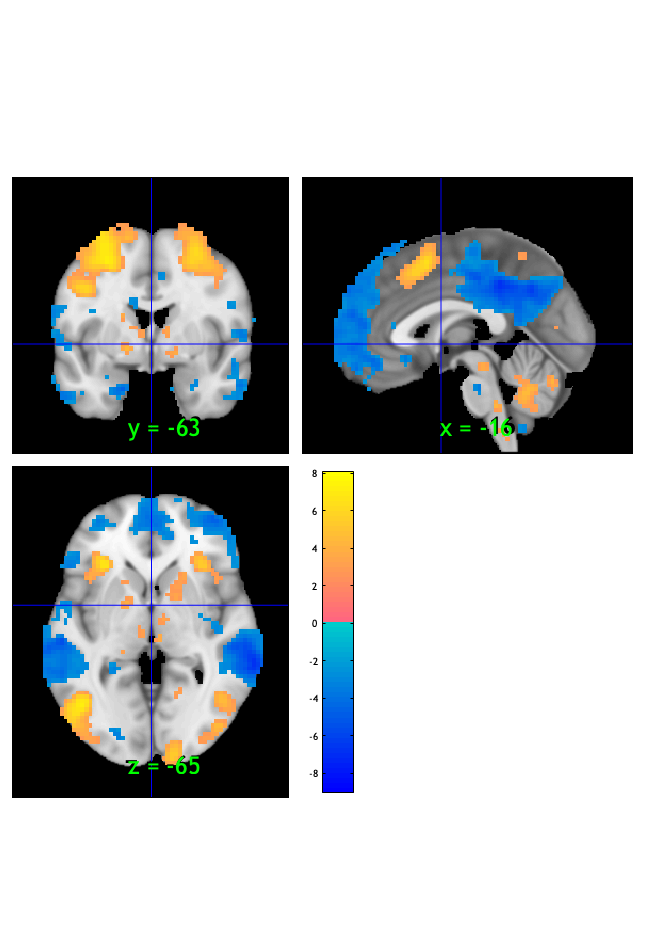

orthviews(fdr_t);

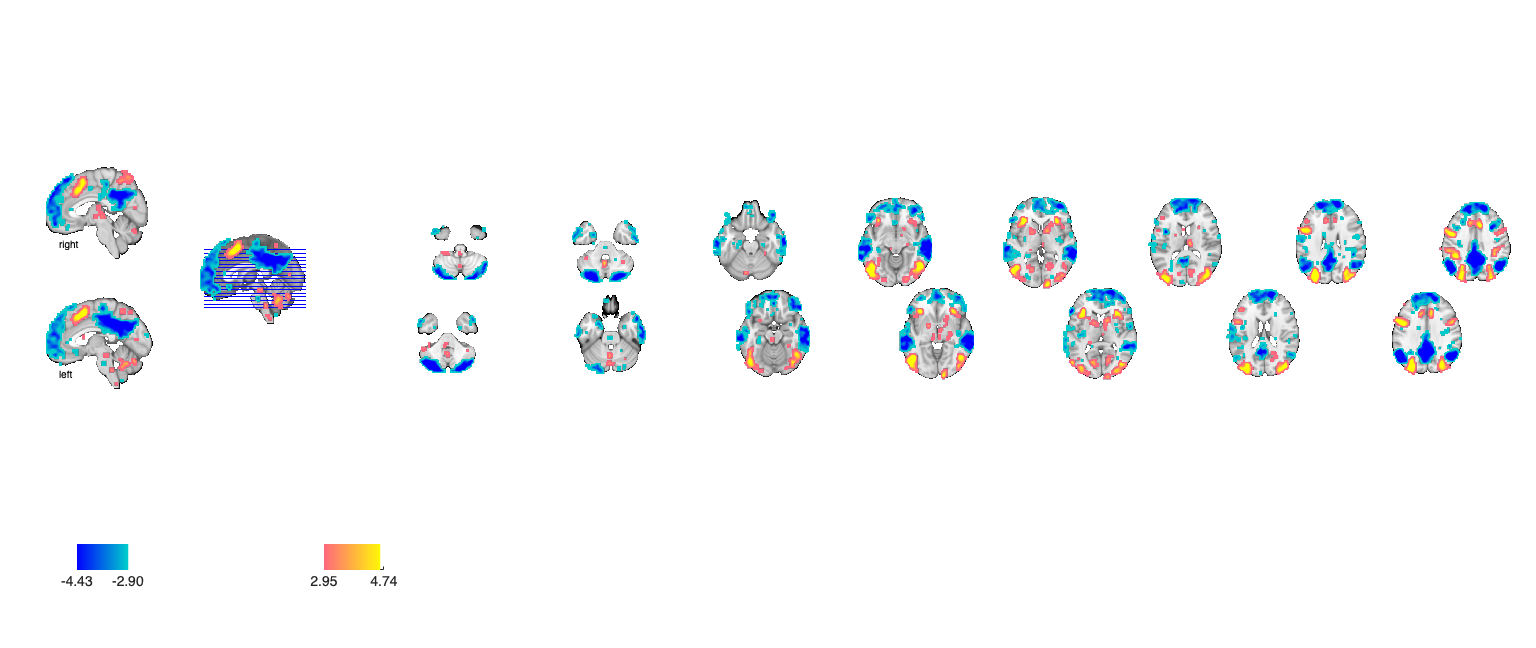

Setting up fmridisplay objects
sagittal montage: 629 voxels displayed, 22454 not displayed on these slices
sagittal montage: 522 voxels displayed, 22561 not displayed on these slices
sagittal montage: 632 voxels displayed, 22451 not displayed on these slices
axial montage: 4447 voxels displayed, 18636 not displayed on these slices
axial montage: 4795 voxels displayed, 18288 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;



#### Cognitive only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low        testr_high       words_high   
    _________    ________________    __________    ________________

    -0.33101     {'person'      }     0.37075      {'visual'      }
    -0.32128     {'trait'       }     0.31295      {'eye'         }
    -0.29793     {'social'      }     0.27134      {'target'      }
    -0.29385     {'default'     }      0.2693      {'saccade'     }
    -0.29364     {'personal'    }     0.26873      {'maintenance' }
    -0.28658     {'self'        }     0.26547      {'letter'      }
    -0.27309     {'positive'    }     0.25008      {'visuospatial'}
    -0.26656     {'rating'      }     0.24999      {'spatial'     }
    -0.26455     {'negative'    }      0.2418      {'shape'       }
     -0.2645

Cognitive only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0028	-0.4842	0.6297	0.0000	
Cog Wholebrain	-0.0221	-4.2049	0.0001	1.0000	
Emo Wholebrain	0.0225	3.2433	0.0018	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T            P         Cohens_d 
    ___________________    __________    _________    ________    __________    _________

    {'Pain Wholebrain'}    -0.0028482    0.0058925    -0.48336       0.63023    -0.055084
    {'Cog Wholebrain' }     -0.022081    0.0052491     -4.2065    7.0213e-05     -0.47938
    {'Emo Wholebrain' }      0.022472    0.0069251       3.245     0.0017472      0.36981



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {77×3 cell}
        text_han: {77×3 cell}
       point_han: {77×3 cell}
    star_handles: [11.0015 12.0015 13.0015]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T            P         Cohens_d 
    ___________________    __________    _________    ________    __________    _________

    {'Pain Wholebrain'}    -0.0028422    0.0058535    -0.48555       0.62868    -0.055334
    {'Cog Wholebrain' }     -0.021292    0.0051073     -4.1689    8.0317e-05     -0.47509
    {'Emo Wholebrain' }      0.022339    0.0069743      3.2031     0.0019872      0.36502



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {77×3 cell}
        text_han: {77×3 cell}
       point_han: {77×3 cell}
    star_handles: [14.0015 15.0015 16.0013]


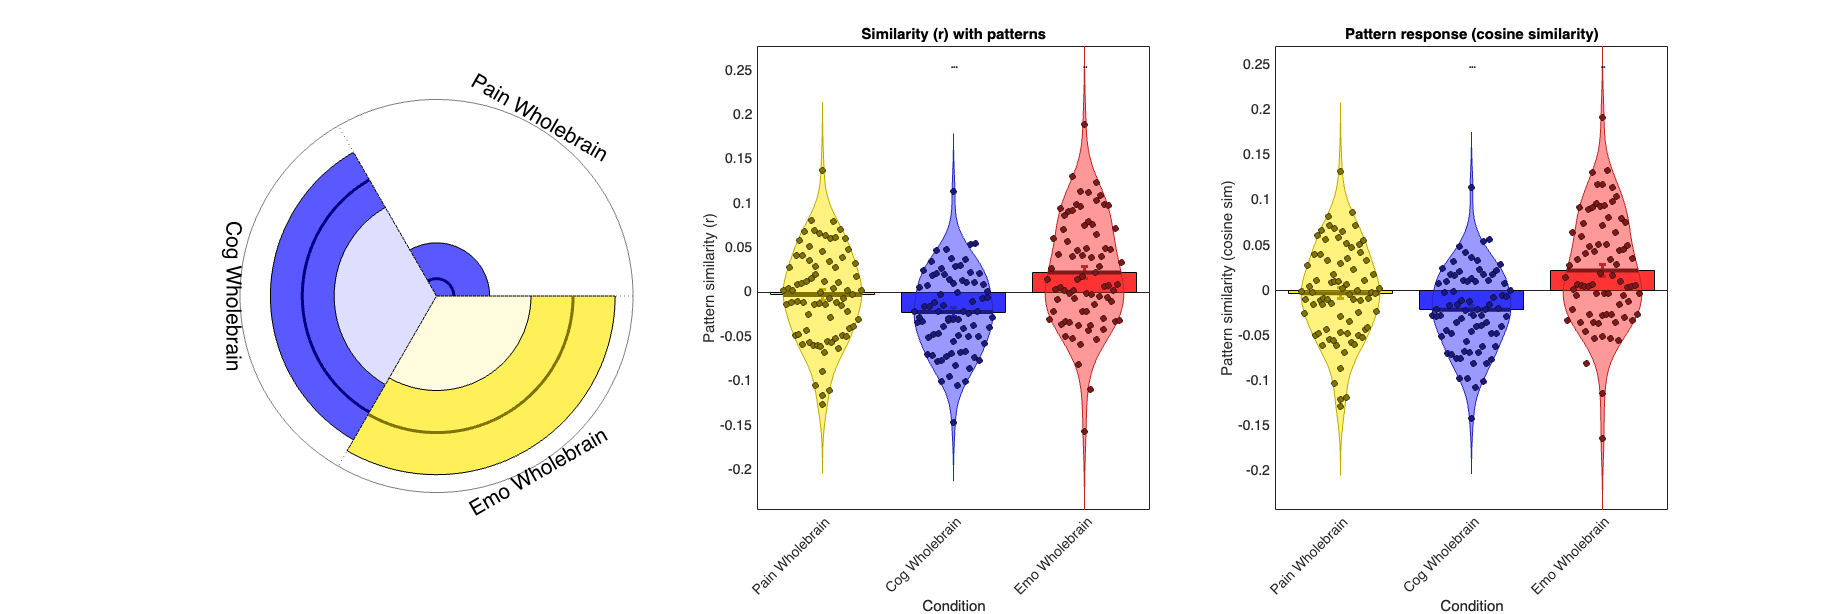

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;


# Manipulation check Rating

# motor contrast

#### motor only :: load dataset

clear all; close all;
contrast_of_interest = 'motor'

contrast_of_interest = 'motor'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond/1stLevel';
contrast_name = {'P_VC_cue_high_gt_low', 'V_PC_cue_high_gt_low', 'C_PV_cue_high_gt_low', ...
'P_VC_stimlin_high_gt_low', 'V_PC_stimlin_high_gt_low', 'C_PV_stimlin_high_gt_low',...
'P_VC_stimquad_med_gt_other', 'V_PC_stimquad_med_gt_other', 'C_PV_stimquad_med_gt_other',...
'P_VC_cue_int_stimlin','V_PC_cue_int_stimlin', 'C_PV_cue_int_stimlin',...
'P_VC_cue_int_stimquad','V_PC_cue_int_stimquad','C_PV_cue_int_stimquad',...
'motor',...
'P_simple_cue_high_gt_low', 'V_simple_cue_high_gt_low', 'C_simple_cue_high_gt_low', ...
'P_simple_stimlin_high_gt_low', 'V_simple_stimlin_high_gt_low', 'C_simple_stimlin_high_gt_low',...
'P_simple_stimquad_med_gt_other', 'V_simple_stimquad_med_gt_other', 'C_simple_stimquad_med_gt_other',...
'P_simple_cue_int_stimlin', 'V_simple_cue_int_stimlin', 'C_simple_cue_int_stimlin',...
'P_simple_cue_int_stimquad','V_simple_cue_int_stimquad','C_simple_cue_int_stimquad'
};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 31548492 bytes
Loading image number:    79
Elapsed time is 3.285528 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7552264  Bit rate: 22.85 bits


#### motor only :: `check data coverage`

m = mean(con_data_obj);
% m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              17:01:59 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


#### motor only :: Plot diagnostics, before l2norm

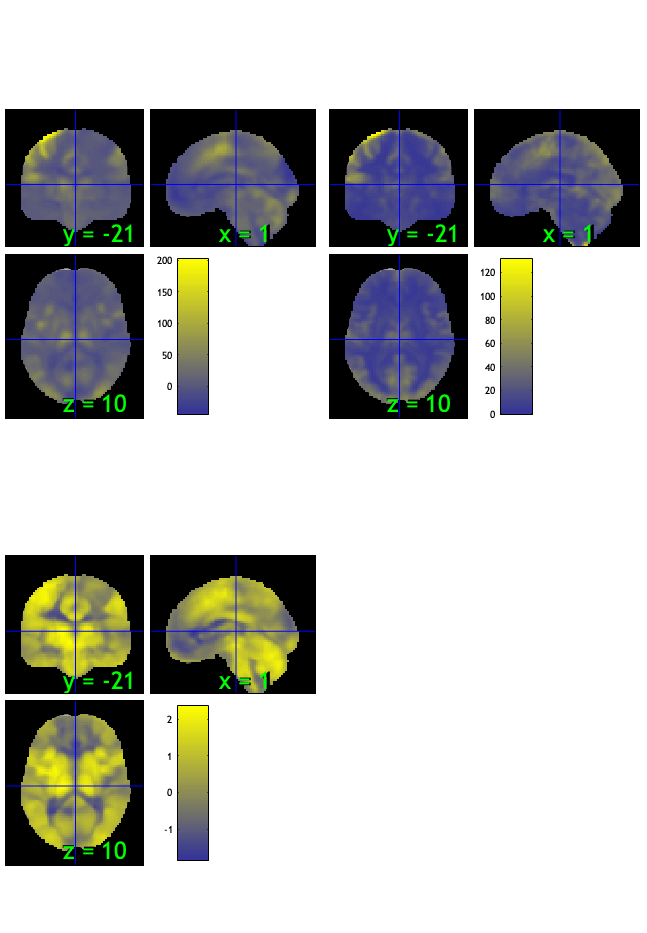

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 41.77%
Expected 3.95 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 12 
Uncorrected: 7 images		Cases 3 12 20 22 46 52 79 

Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 48.10%
Expected 3.95 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 18 
Uncorrected: 5 images		Cases 9 18 54 64 73 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                          

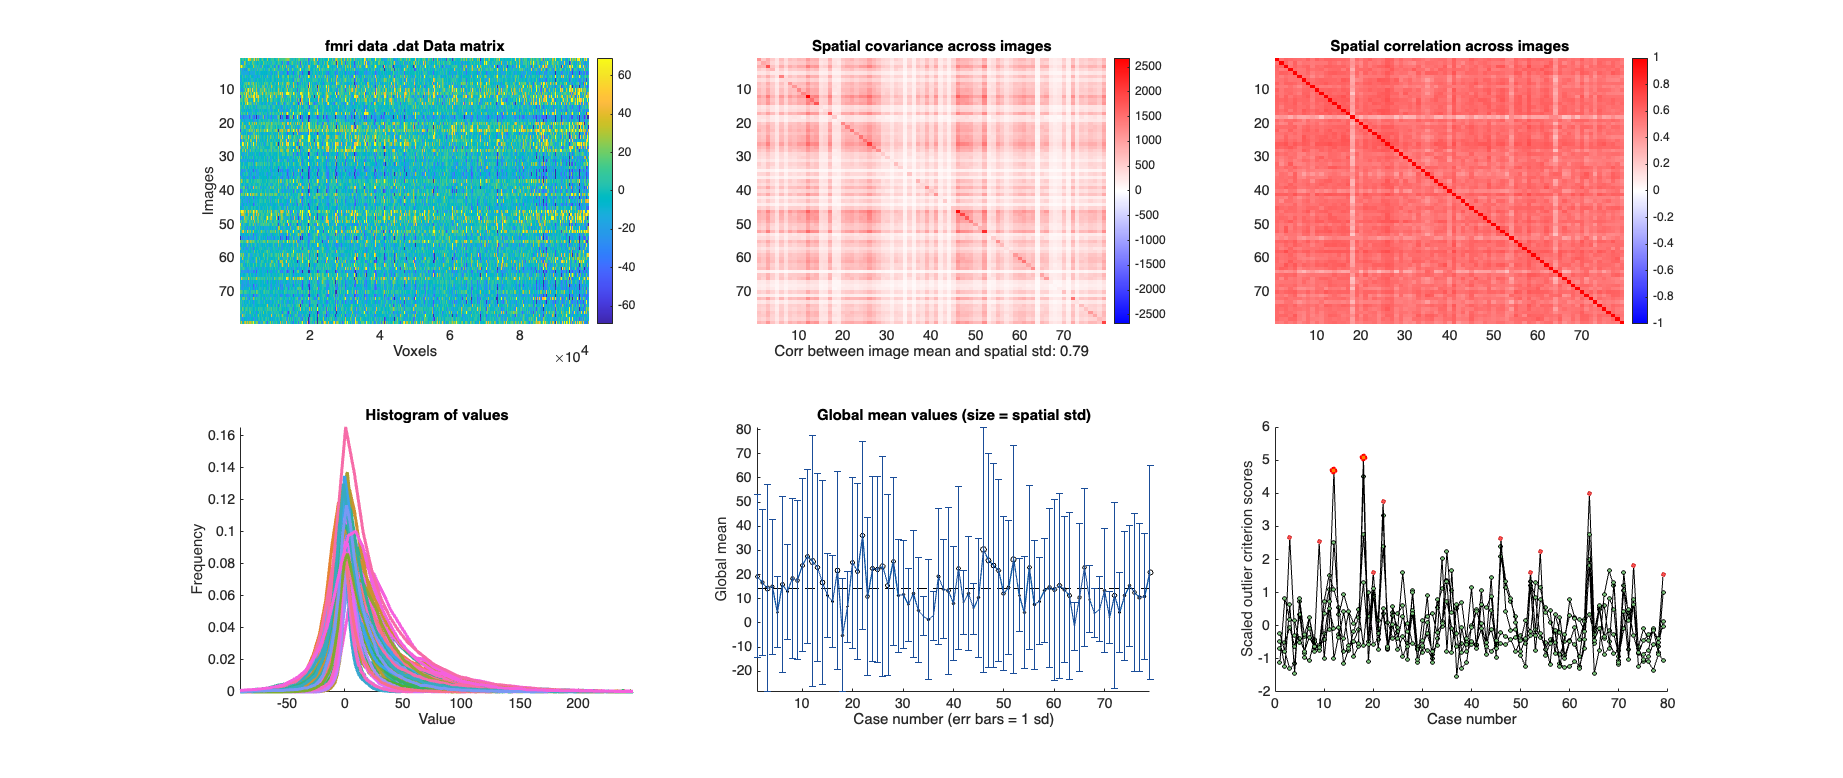

SPM12: spm_check_registration (v7759)              17:02:23 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### motor only :: run robfit

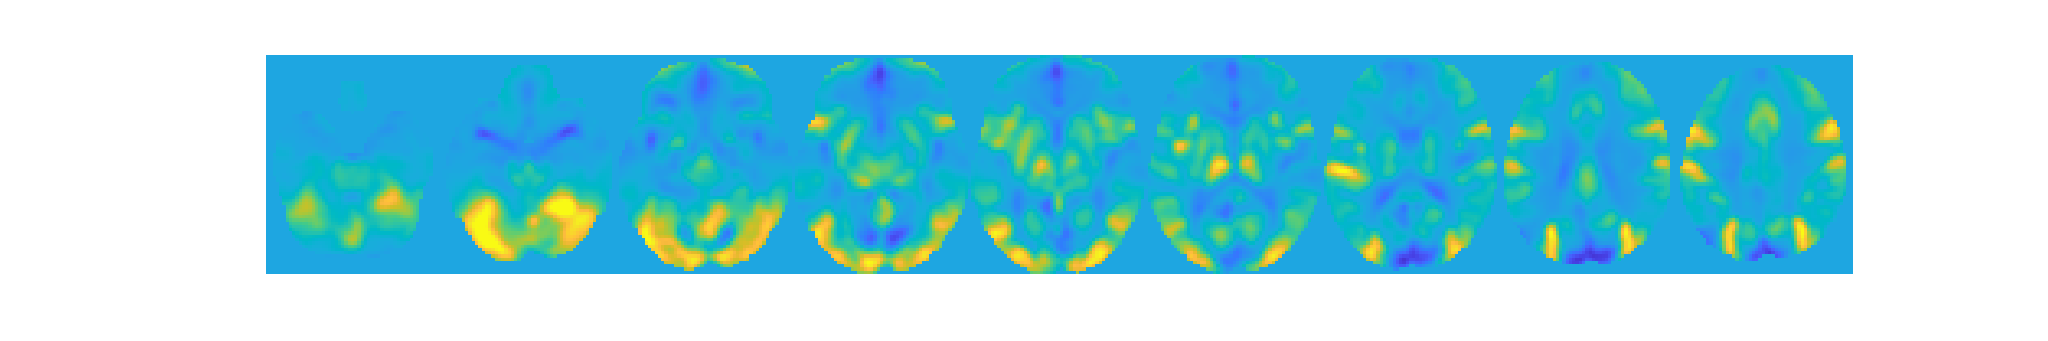

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### motor only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 79


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 2 participants, size is now 77


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0036"    "participants that are outliers:... sub-0044"



disp(n);

    {'sub-0036'}    {'sub-0044'}



#### motor only:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### motor only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


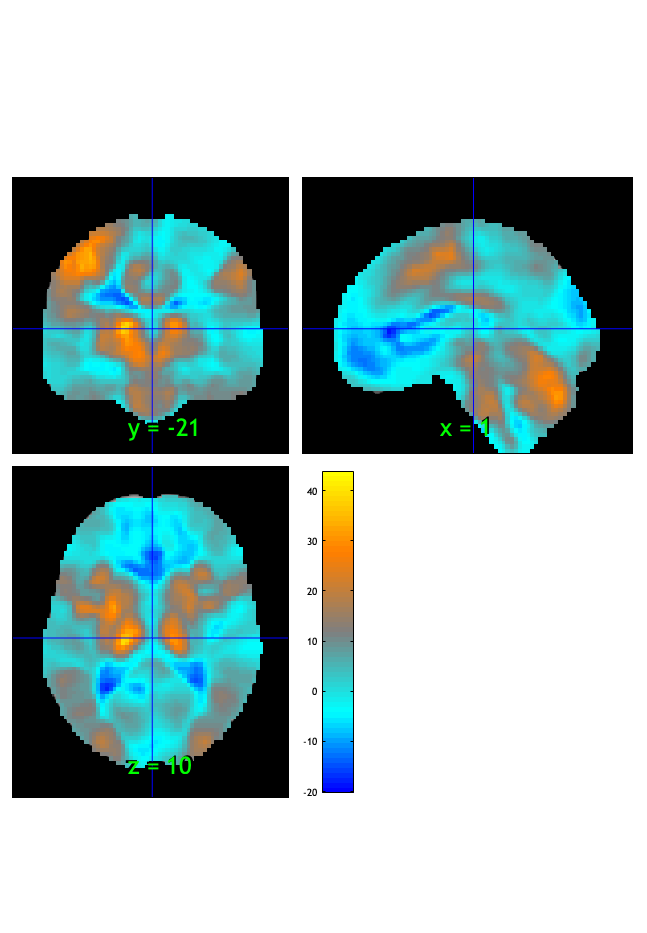

SPM12: spm_check_registration (v7759)              17:02:28 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.041430

Image   1
  8 contig. clusters, sizes   1 to 82731
Positive effect: 67048 voxels, min p-value: 0.00000000
Negative effect: 15702 voxels, min p-value: 0.00000000


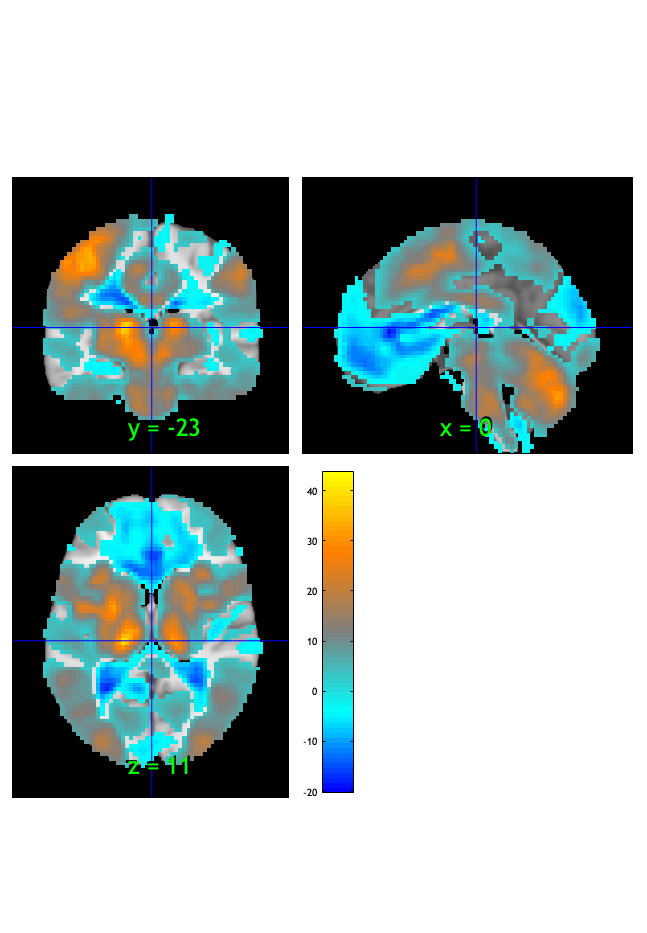

SPM12: spm_check_registration (v7759)              17:02:29 - 11/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


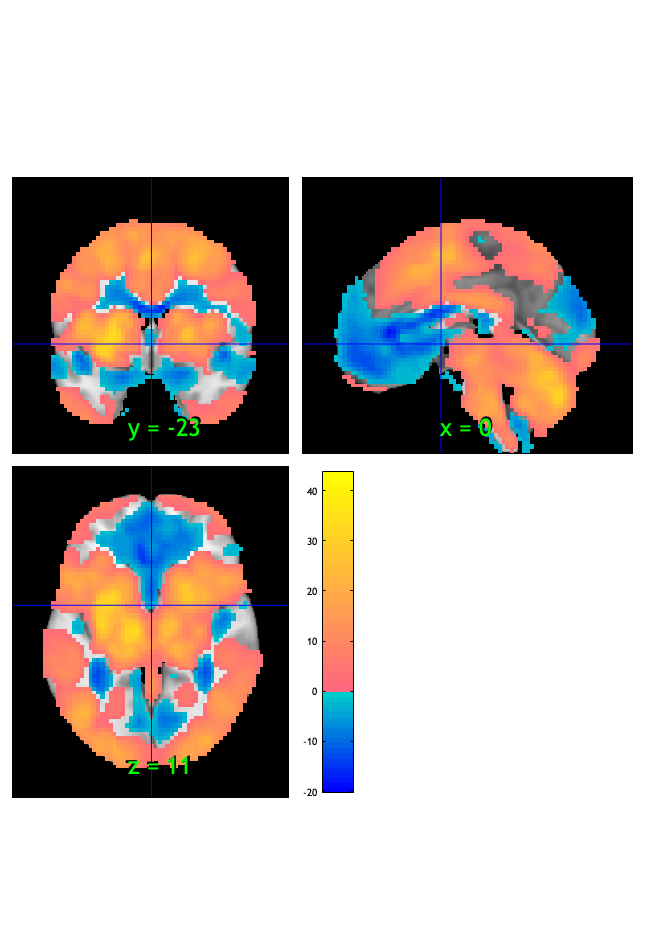

orthviews(fdr_t);

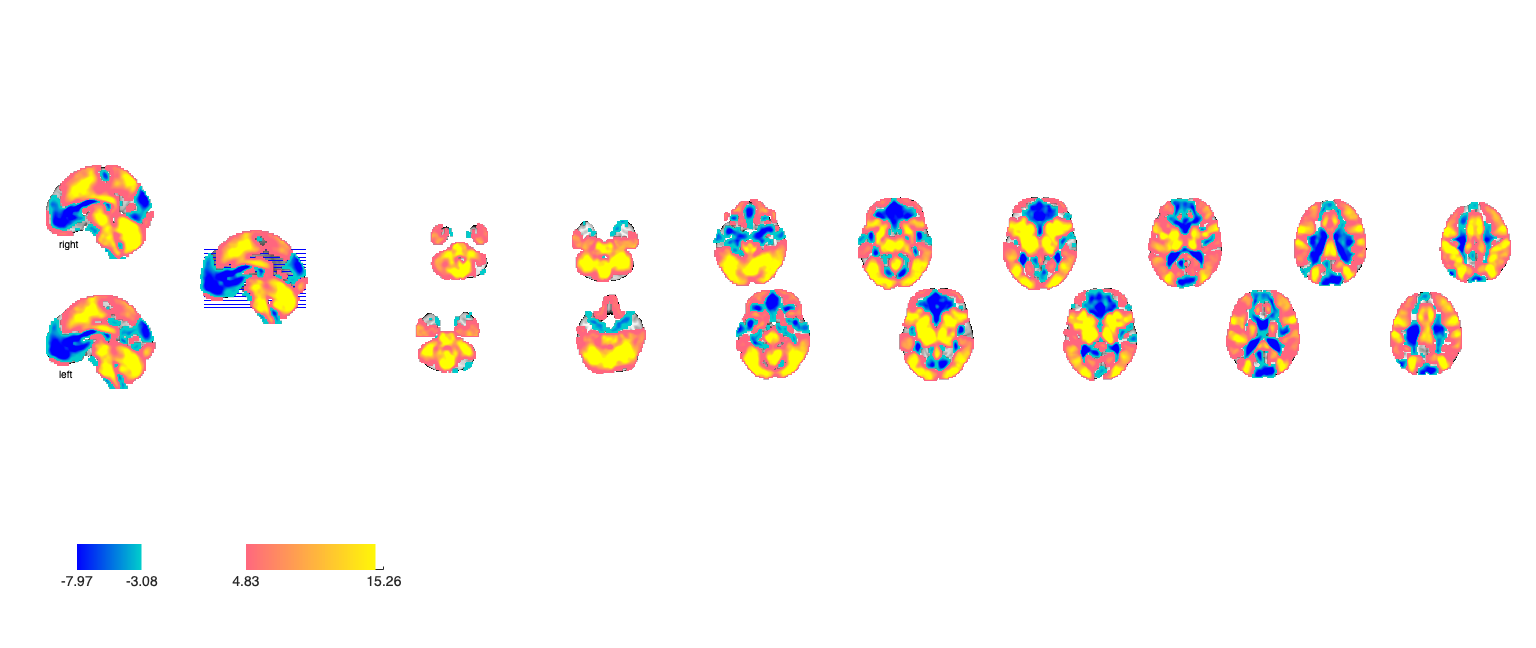

Setting up fmridisplay objects
sagittal montage: 2056 voxels displayed, 80694 not displayed on these slices
sagittal montage: 2049 voxels displayed, 80701 not displayed on these slices
sagittal montage: 1957 voxels displayed, 80793 not displayed on these slices
axial montage: 15332 voxels displayed, 67418 not displayed on these slices
axial montage: 16656 voxels displayed, 66094 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;



#### motor only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low       testr_high       words_high   
    _________    ______________    __________    ________________

    -0.33543     {'trait'     }     0.38437      {'movements'   }
    -0.32531     {'positive'  }     0.35965      {'execution'   }
    -0.32445     {'negative'  }     0.35291      {'hand'        }
    -0.31046     {'age'       }     0.32873      {'visual'      }
    -0.29781     {'personal'  }     0.32741      {'motor'       }
    -0.29388     {'depression'}     0.31177      {'finger'      }
    -0.28953     {'disorder'  }      0.2861      {'action'      }
    -0.28951     {'emotion'   }     0.28516      {'sensorimotor'}
    -0.28853     {'affect'    }     0.28514      {'hands'       }
    -0.28487     {'rating'    }   

motor only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0208	-5.0825	0.0000	1.0000	
Cog Wholebrain	0.0321	13.3412	0.0000	1.0000	
Emo Wholebrain	-0.0091	-2.2137	0.0298	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.020811    0.0040941    -5.0831    2.4843e-06     -0.5719
    {'Cog Wholebrain' }      0.032137    0.0024069     13.352    2.2204e-15      1.5022
    {'Emo Wholebrain' }    -0.0090857    0.0041032    -2.2143       0.02973    -0.24912



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {79×3 cell}
        text_han: {79×3 cell}
       point_han: {79×3 cell}
    star_handles: [13.0009 14.0009 15.0009]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.016182      0.003696    -4.3783    3.6736e-05     -0.4926
    {'Cog Wholebrain' }     0.029182     0.0022008      13.26    2.2204e-15      1.4919
    {'Emo Wholebrain' }    -0.011382     0.0037577    -3.0289     0.0033269    -0.34078



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {79×3 cell}
        text_han: {79×3 cell}
       point_han: {79×3 cell}
    star_handles: [16.0007 17.0006 18.0006]


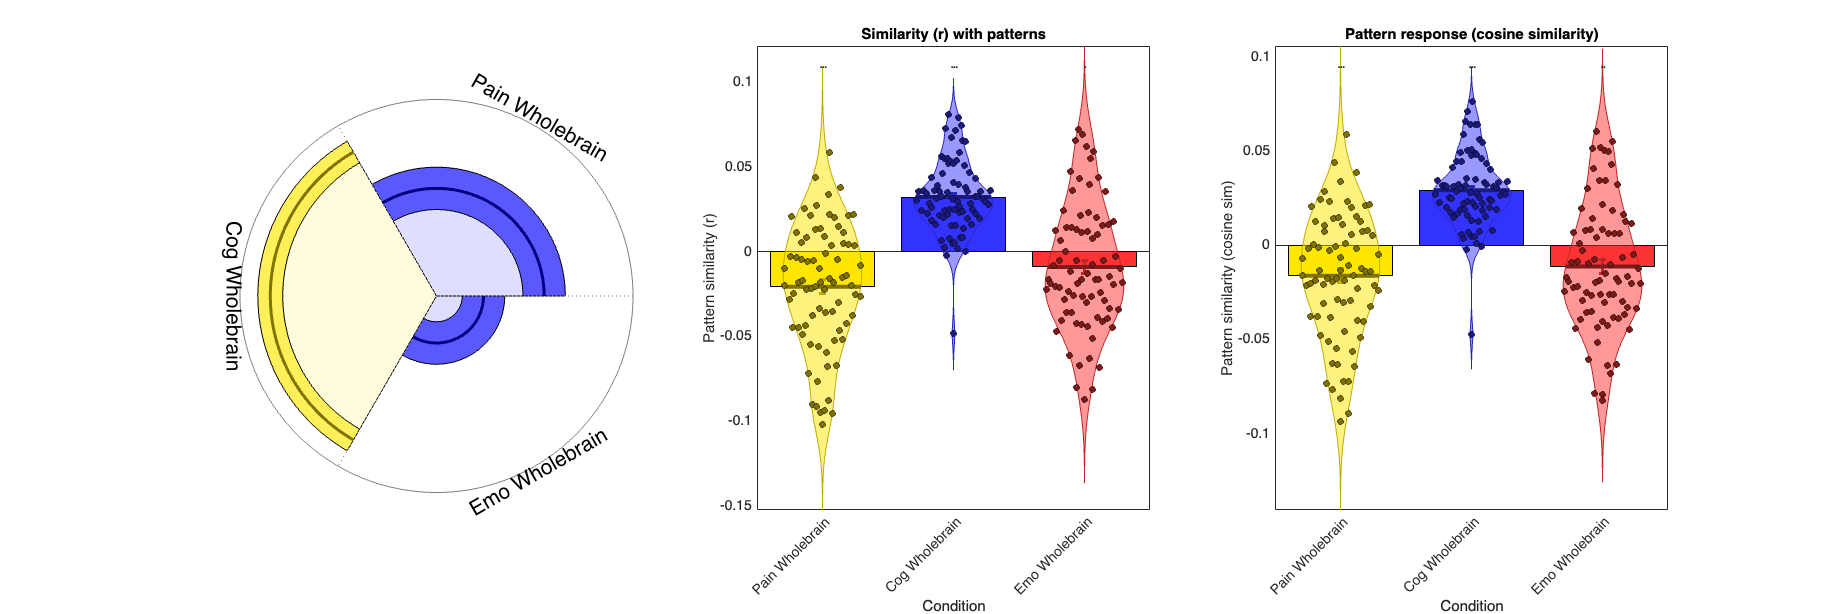

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;


% save html
% pubdir = pwd;
% pubfilename = '6cond_cueeffect_contrast.mlx';
% 
% p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
%   'format', 'html', 'outputDir', pubdir, ...
%   'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
% htmlfile = publish(pubfilename, p);